% chenzhe, 2019-07-07, script to check a hypothesis:
% (1) For non-twinned grains, higher basal SF grains should have higher effective strain
%


clear;
addChenFunction;

% grainDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab\Grain_1144_data_for_paper_ppt','Folder to save the grain data'),'\'];
dicPath = uigetdir('D:\WE43_T6_C1_insitu_compression\stitched_DIC','pick DIC directory, which contains the stitched DIC data for each stop');
% dicFiles = dir([dicPath,'\*.mat']);
% dicFiles = struct2cell(dicFiles);
% dicFiles = dicFiles(1,:)';

% looks like have to include this part to read the sample name.
[fileSetting,pathSetting] = uigetfile('','select setting file which contains sampleName, stopNames, FOVs, translations, etc');
load_settings([pathSetting,fileSetting],'sampleName','cpEBSD','cpSEM','sampleMaterial','stressTensor','strainPauses');

% load previous data and settings
saveDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab','choose a path of the saved processed data, or WS, or etc.'),'\'];
saveDataPathInput = saveDataPath;
load([saveDataPath,sampleName,'_traceAnalysis_WS_settings.mat']);
if ~strcmpi(saveDataPath,saveDataPathInput)
    disp('Input saveDataPath is different from that saved in setting.mat file. Check files or code.');
    return;
end

% Load from the pre-labeled results: twinMap, sfMap, struCell.  (cToGbDistMap is omitted, as will no longer be used in this code)
[confirmedLabelFile, confirmedLabelPath] = uigetfile('D:\p\m\DIC_Analysis\','select the results where twin identification was based on trace dir and strain');

[twinGbIntersectionFile, twinGbIntersectionPath] = uigetfile('D:\p\m\DIC_Analysis\20190222_1246_twin_at_boundary_result.mat','select the results for twin-grain boundary intersection');

try
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
catch
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
end
% modify / or keep an eye on these settings for the specific sample to analyze  ------------------------------------------------------------------------------------
STOP = {'0','1','2','3','4','5','6','7'};
B=1;    % 0-based B=1.  1-based B=0.
iE_start = 2;   % elongation levels to analyze. 0-based.
iE_stop = 5;

% file name prefixes
f1 = 'WE43_T6_C1_s';
f2 = '_';

debugTF = 0;

## [data] strain data. Convert into v7.3 for partial loading

clear strainFile;
for iE = iE_start-1:iE_stop
    strainFileName = [dicPath,'\',f2,STOP{iE+B}];
    disp(strainFileName);
    if ~exist([strainFileName,'_v73.mat'],'file')
        load(strainFileName);
        clear('exy_corrected');
        load(strainFileName,'exy_corrected');   % if 'exy_corrected' does not exist, this does not give error, rather, just warning.
        
        if exist('exy_corrected','var')&&(1==exy_corrected)
            disp('================= exy already corrected ! ========================');
            exy_corrected = 1;
        else
            disp('================= exy being corrected here ! =======================');
            exy = -exy;
            exy_corrected = 1;
        end
        % remove bad data points
        exx(sigma==-1) = nan;
        exy(sigma==-1) = nan;
        eyy(sigma==-1) = nan;
        qt_exx = quantile(exx(:),[0.0013,0.9987]); qt_exx(1)=min(-1,qt_exx(1)); qt_exx(2)=max(1,qt_exx(2));
        qt_exy = quantile(exy(:),[0.0013,0.9987]); qt_exy(1)=min(-1,qt_exy(1)); qt_exy(2)=max(1,qt_exy(2));
        qt_eyy = quantile(eyy(:),[0.0013,0.9987]); qt_eyy(1)=min(-1,qt_eyy(1)); qt_eyy(2)=max(1,qt_eyy(2));
        ind_outlier = (exx<qt_exx(1))|(exx>qt_exx(2))|(exy<qt_exy(1))|(exy>qt_exy(2))|(eyy<qt_eyy(1))|(eyy>qt_eyy(2));
        exx(ind_outlier) = nan;
        exy(ind_outlier) = nan;
        eyy(ind_outlier) = nan;
        
        outlier_removed = 1;
        save([strainFileName,'_v73.mat'],'outlier_removed','exy_corrected','-v7.3');
        
        myFile = matfile(strainFileName);
        myFields = who(myFile);
        for ii=1:length(myFields)
            save([strainFileName,'_v73.mat'],myFields{ii},'-append','-v7.3');
        end
    else
        disp('v7.3 file already exist');
    end
    strainFile{iE} = matfile([strainFileName,'_v73.mat']);
end

## (0) load data, using SF threshold values to assign active twin system, and make maps

Load cluster number maps (cleaned).

clusterNumberMapCell = cell(1,length(STOP)-1);
for iE = []                                         %iE_start:iE_stop
    fName_c2t_result = [sampleName,'_s',num2str(STOP{iE+B}),'_cluster_to_twin_result.mat'];
    load([saveDataPath,fName_c2t_result],'clusterNumMapCleaned');
    clusterNumberMapCell{iE} = clusterNumMapCleaned;
end

% Load from the pre-labeled results: twinMapCell, sfMapCell, struCell.  (cToGbDistMapCell is omitted, as will no longer be used in this code)
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'struCell','twinMapCell','trueTwinMapCell','sfMapCell','tNote');
load(fullfile(confirmedLabelPath,confirmedLabelFile),'trueTwinMapCell');

% load previous twin_gb interaction result
load(fullfile(twinGbIntersectionPath, twinGbIntersectionFile));

Note: hypothesis is that: if not twinned, high basal SF -> high strain Test hypothesis?

[ssa, c_a, nss, ntwin, ssGroup] = define_SS(sampleMaterial,'twin');
ss = crystal_to_cart_ss(ssa,c_a);

% create a basal schmid factor map
grain_basal_SF = []; 
for ii = 1:length(gID)
   ID_current = gID(ii);
   ind = find(ID_current==gID);
   [abs_schmid_factor, ~, ~] = trace_analysis_TiMgAl([gPhi1(ind),gPhi(ind),gPhi2(ind)], [0 0 0], [0 0 0], stressTensor, 'Mg', 'twin');
   grain_basal_SF(ii) = max(abs_schmid_factor(1:3,2));
end
basal_SF_map = assign_field_to_cell(ID, gID, grain_basal_SF);
save('temp_results\temp_basal_SF_map.mat','basal_SF_map')

## Q1: for the non-twinned grains, does higher strain [-](#-) higher basal SF?

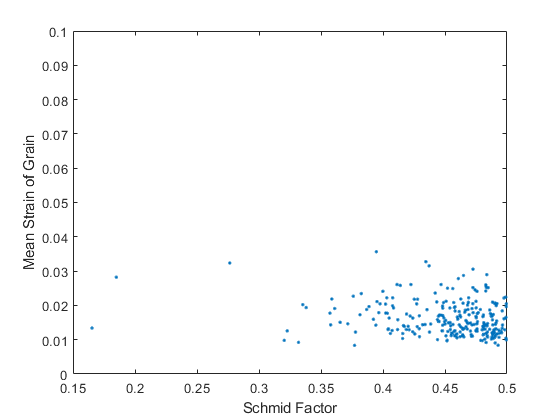

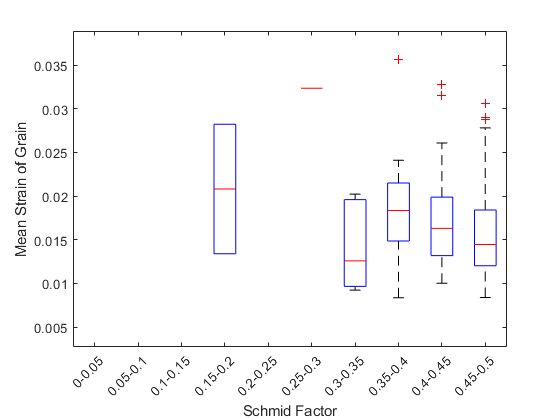

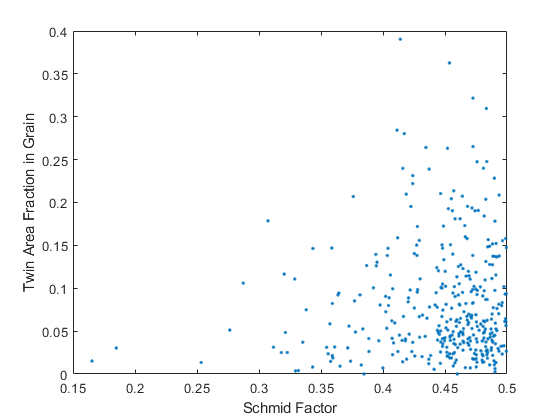

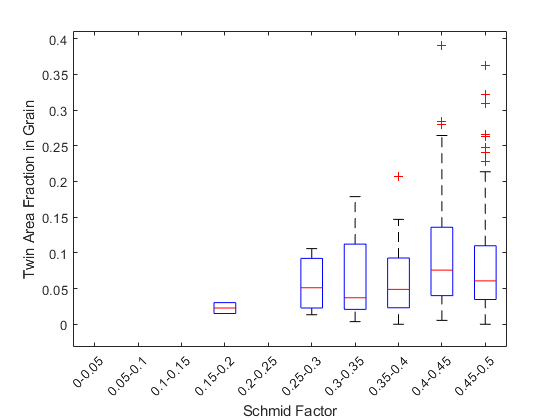

for iE = 3

eEff = effective_strain(strainFile{iE}.exx, strainFile{iE}.exy, strainFile{iE}.eyy);

% Table_1, for grain summaries
variableNames = {'iE','ID','e1','e5','e10','e50','e90','e95','e99','emean','basal_SF','twin_SF','twinnedTF'};
T = cell2table(cell(0,length(variableNames)));
T.Properties.VariableNames = variableNames;

% Table_2, only for variants of twins
variableNames2 = {'iE','ID','ts','variant','twin_SF','v1_TF','vPct'};
T2 = cell2table(cell(0,length(variableNames2)));
T2.Properties.VariableNames = variableNames2;

% Table_3, for mPrime
variableNames3 = {'iE','ID','ts','ID_neighbor','mPrime'};
T3 = cell2table(cell(0,length(variableNames3)));
T3.Properties.VariableNames = variableNames3;
mPrimeMap = zeros(size(uniqueBoundary));
mPrimeMap(uniqueBoundary>0) = -1;

ID_twinned = [];
for iS = 1:length(struCell{iE})
    ID_current = struCell{iE}(iS).gID;
    
    ind_local = ismember(ID, ID_current); %ismember(ID, [ID_current,ID_neighbor]);
    % Make it one data point wider on each side
    indC_min = max(1, find(sum(ind_local, 1), 1, 'first')-1);
    indC_max = min(size(ID,2), find(sum(ind_local, 1), 1, 'last')+1);
    indR_min = max(1, find(sum(ind_local, 2), 1, 'first')-1);
    indR_max = min(size(ID,1), find(sum(ind_local, 2), 1, 'last')+1);
    
    ID_local = ID(indR_min:indR_max, indC_min:indC_max);
    
    % [*] Calculate the max basal Schmid factor of this grain
    ind = find(ID_current==gID);
    euler_current = [gPhi1(ind),gPhi(ind),gPhi2(ind)];
    [abs_schmid_factor, ~, burgersXY] = trace_analysis_TiMgAl(euler_current, [0 0 0], [0 0 0], stressTensor, 'Mg', 'twin');
    basal_SF = max(abs_schmid_factor(1:3,2));
    
    %     uniqueBoundary_local = uniqueBoundary(indR_min:indR_max, indC_min:indC_max);
    map_local = eEff(indR_min:indR_max, indC_min:indC_max);
    map_local(ID_local~=ID_current) = nan;
    
    es = [quantile(map_local(:), [0.01, 0.05, 0.1, 0.5, 0.9, 0.95, 0.99]), nanmean(map_local(:))];
    
    % find out new activeTS
    activeTS = logical(sum(struCell{iE}(iS).cTrueTwin,1));
    if iE==iE_start
        activeTS_pre = [0 0 0 0 0 0];
    else
        activeTS_pre = logical(sum(struCell{iE-1}(iS).cTrueTwin,1));
    end
    newActiveTS = (activeTS - activeTS_pre)>0;      % --> ---------------------------------> we may choose between all activeSS or newActiveSS 
    tSFs = struCell{iE}(iS).tSF;
    [~,SF_order]=ismember(tSFs,sort(tSFs,'descend'));   % find index of ranking of element in array
    
    % determine if this grain is twinned. If twinned, twin_SF = max of active twin ss.  If not twinned, twin_SF = max of twin ss.  
    if any(activeTS)
        twin_SF = max(struCell{iE}(iS).tSF(sum(struCell{iE}(iS).cTrueTwin,1)>0));
        T = [T; {iE, ID_current, es(1),es(2),es(3),es(4),es(5),es(6),es(7),es(8), basal_SF, twin_SF, true}];
        ID_twinned = [ID_twinned; ID_current];
    else
        twin_SF = max(struCell{iE}(iS).tSF);
        T = [T; {iE, ID_current, es(1),es(2),es(3),es(4),es(5),es(6),es(7),es(8), basal_SF, twin_SF, false}];
    end
    
    % ii is the twin system index from 1 to 6.
    for ii=1:length(activeTS)
        if activeTS(ii)>0
            [~,idx] = max(struCell{iE}(iS).tSF);
            T2 = [T2; {iE, ID_current, struCell{iE}(iS).tLabel(ii), SF_order(ii), tSFs(ii), activeTS(idx)>0, struCell{iE}(iS).tVol(ii)/struCell{iE}(iS).gVol}];
        end
    end
    
    
    % % %
    % find all twinned grains
    all_twinned_grains = unique(tb_gNum);
    all_involved_grains = unique([floor(tb_gbNum/10000); mod(tb_gbNum,10000)]);
    
    if any(activeTS)
        for iTwin = 1:length(activeTS)
            tgbs = struCell{iE}(iS).tGb{iTwin};    % find all twin gbs related to this twin variant  
            for jj=1:length(tgbs)
                tgb_current = tgbs(jj);
                pairs = [floor(tgb_current/10000), mod(tgb_current,10000)];
                ID_neighbor = pairs(~ismember(pairs,ID_current));   % find neighbor ID 
                
                % Is neighbor twinned ever?
                if ~ismember(ID_neighbor, all_twinned_grains)
                    % find euler angle of neighbor grain
                    ind = find(ID_neighbor==gID);
                    euler_neighbor = [gPhi1(ind),gPhi(ind),gPhi2(ind)];
                    [schmidFactorG1, schmidFactorG2, mPrimeMatrix, resBurgersMatrix, mPrimeMatrixAbs, resBurgersMatrixAbs] = calculate_mPrime_and_resB(euler_current, euler_neighbor, stressTensor, [1 0 0], sampleMaterial, 'twin');
                    mPrime = mPrimeMatrixAbs(19:24,1:3);
                    mPrime = max(mPrime(iTwin,:));      % max of this twin w.r.t a basal slip in neighbor  
                    mPrimeMap(uniqueBoundary==tgb_current) = mPrime;
                    
                    T3 = [T3; {iE, ID_current, struCell{iE}(iS).tLabel(ii), ID_neighbor, mPrime}];
                    % Can also find local strain in neighbor from gb. 
                end
            end
        end
    end
    
    
end

%% [*] [Plot] selected strain (e.g., median strain vs. basal_SF)
ind = (T.twinnedTF==1);                 % ---------------------------> Select which (twinned or non-twinned) grain
vx = T.twin_SF(ind);                    % ---------------------------> Select which SF here
vy = T.emean(ind);                      % ---------------------------> Select strain here
ylabel_str = 'Mean Strain of Grain';    % ---------------------------> change name 

figure;
plot(vx, vy, '.');
set(gca,'ylim',[0 0.1])
xlabel('Schmid Factor'); ylabel(ylabel_str);

% [*] Summarize by [boxplot].
edges = 0:0.05:0.5;
gv = discretize(vx, edges);
nGroups = length(edges)-1;
clear labels;
for ii = 1:length(edges)-1
    labels{ii} = [num2str(edges(ii)),'-',num2str(edges(ii+1))];
end

figure;
boxplot([vy; nan*ones(nGroups,1)], [gv; (1:nGroups)']);     % sometimes, a group does not have anything. This make sure we have all group variables.   
xlabel('Schmid Factor'); ylabel(ylabel_str);  
set(gca,'xticklabels',labels,'xticklabelrotation',45);
% set(gca,'ylim',[0 0.04])


%% [*] [boxplot] to show twin_area_fraction vs twin_SF
edges = 0:0.05:0.5;
vx = T2.twin_SF;                   % ---------------------------> Select which SF here
vy = T2.vPct;                      % ---------------------------> Select strain here
ylabel_str = 'Twin Area Fraction in Grain';    % ---------------------------> change name 

figure;
plot(vx, vy, '.');
xlabel('Schmid Factor'); ylabel(ylabel_str);
% set(gca,'ylim',[0 0.1])

gv = discretize(vx, edges);
nGroups = length(edges)-1;
clear labels;
for ii = 1:length(edges)-1
    labels{ii} = [num2str(edges(ii)),'-',num2str(edges(ii+1))];
end
figure;
boxplot([vy; nan*ones(nGroups, 1)], [gv; (1:nGroups)']);
xlabel('Schmid Factor'); ylabel(ylabel_str)
set(gca,'xticklabels',labels,'xticklabelrotation',45);

%% we can test if the Pearson's correlation coefficient is 'significantly different from 0'
% create 2 [Maps] of strain, twinned and non-twinned
m_ind_twinned = ismember(ID,ID_twinned);
m_ind_not_twinned = ~m_ind_twinned;

eMap_twinned = eEff;
eMap_twinned(m_ind_not_twinned) = nan;

eMap_not_twinned = eEff;
eMap_not_twinned(m_ind_twinned) = nan;

% myplot(eMap_twinned);
% myplot(eMap_not_twinned);

%%
timeStr = datestr(now,'yyyymmdd_HHMM');
save(['temp_results\script_11_data_iE_',num2str(iE),'_',timeStr,'.mat'],'T','T2','T3', 'ID_twinned','eMap_twinned','eMap_not_twinned')




end

## check mPrimeMap

map = mPrimeMap;
for ii=1:2
    map = imdilate(map,ones(3));
    map(trueTwinMapCell{iE}>0) = 1;
end
myplot(map)
myplot(strainFile{iE}.exx,boundaryTFB)